# Spring-Wing simulation

In order to break down the important elements of spring-wing dynamics, we need a framework that enables us to quickly swap out and compare different versions of the model. In general,


$$I(t)\ddot{\theta}+f_d(\dot{\theta})+f_e(\theta) =u(\mathbf{\theta},t)$$


Where $I$ is the inertia of the system, which may be a function of time, $f_d$ is the drag function (aero, viscous, friction, structural, etc.), $f_e$ is the elasticity function (linear spring, hardening or softening spring, etc.), and $u$ is the force applied to the system, which may be a function of the state and/or time.

I'd like to write a function that allows us to specify each of those functions - $I$, $f_d$, $f_e$, $u$ - explicitly to maintain some consistency.

# The *sim_opts *struct

A struct used to feed in the different simulation options. The options that are currently available are:

## Inertia

- *constant - *Inertia does not change during operation. Takes one parameter (the inertia)

## Drag

- *aero - *Quadratic damping such that $F_d = \beta|\dot{\theta}|\dot{\theta}$. Takes one parameter (drag coefficient)

- *viscous - *Viscous damping such that $F_d = \beta\dot{\theta}$. Takes one parameter (viscous coefficient)

## Spring

- *linear - *Constant coefficient linear spring. Takes one parameter (spring stiffness). 

- *mech_stop - *Strain-stiffening spring constructed as a cubic spline such that 


$$K = \left\{
        \begin{array}{ll}
            K_{small} & \quad |x| \leq d_{stop} \\
            K_{large} & \quad |x| \gt d_{stop}
        \end{array}
    \right.

$$


              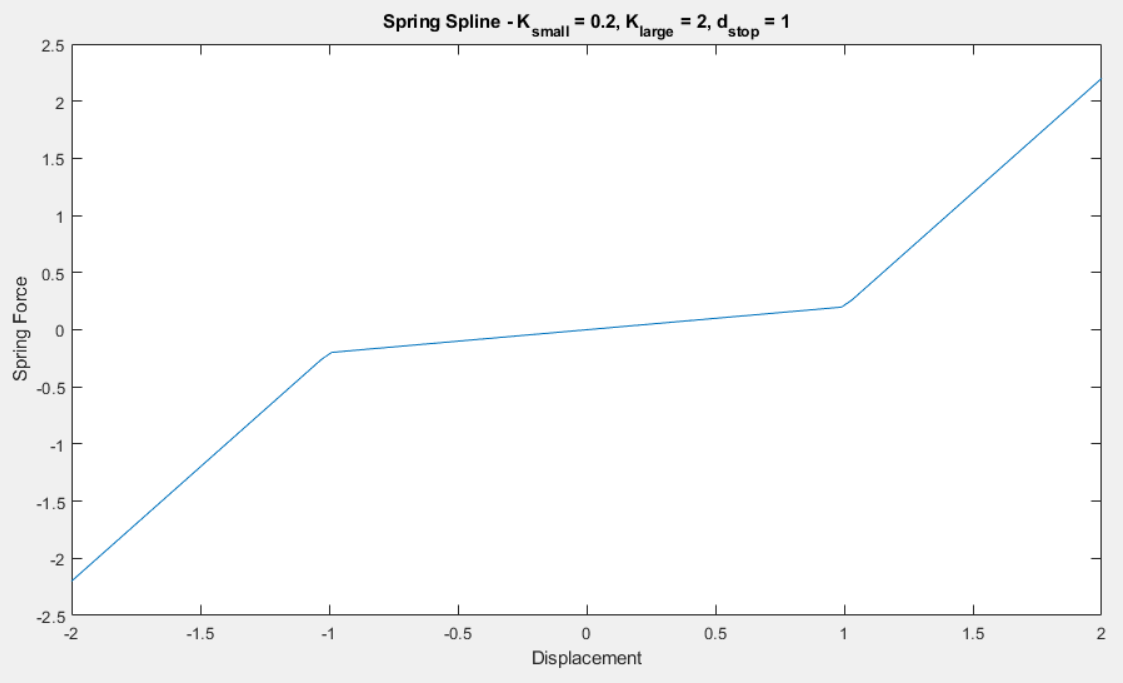

                Takes 3 parameters in a vector, [$K_{small}$, $K_{large}$, $d_{stop}$] 

tic
sim_opts = struct();

sim_opts.inertiaMode    = 'constant';   % Constant inertia
sim_opts.params.inertia = 0.001;       % kg m^2

sim_opts.dragMode       = 'aero';       % Aerodynamic Drag
sim_opts.params.drag    = 0.002;        % drag coeff
% 
% sim_opts.springMode     = 'linear';     % Linear spring
% sim_opts.params.spring  = 0.2;          % Nm/rad
sim_opts.springMode     = 'mech_stop';  % Linear spring
sim_opts.params.spring  = [0.5, 2, 1];     % [soft spring, stiff spring, dStop]

sim_opts.transmissionMode = 'linear';   % Transmission
sim_opts.params.transmission = 1;       % Transmission ratio

sim_opts.forceMode      = 'sinusoid';   % Type of forcing
sim_opts.params.force   = [0.5,2];        % [Amp, Freq]

odefun = springWingFunSetup(sim_opts);

Elapsed time is 0.017750 seconds.


toc
% Run!
tic
[t,y] = ode45(odefun,[0,10],[0,0]);

Elapsed time is 0.055437 seconds.


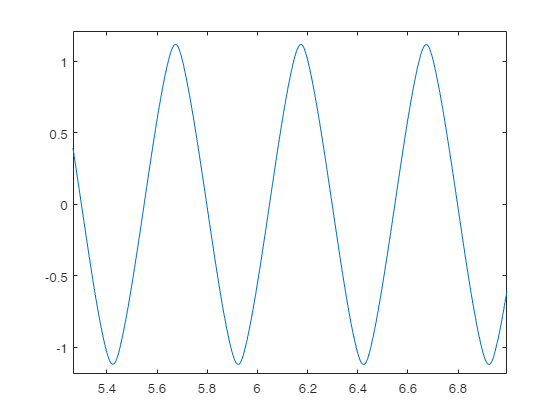

toc

plot(t,y(:,1))

